X = readraw_color("C:\Users\Ellis\Documents\HWFiles\digitalImgProcessing\project1\srcImages\girls.raw");

    "→Retrieving Image "    "C:\Users\Ellis\Documents\HWFiles\di…"    " ..."



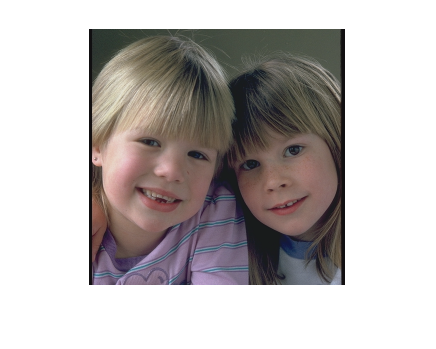

y = X(1,1,:);
imshow(X);

[L, W, c] = size(X);

px = X(1, 1, :);
disp(px);


(:,:,1) =

   17


(:,:,2) =

   15


(:,:,3) =

   17



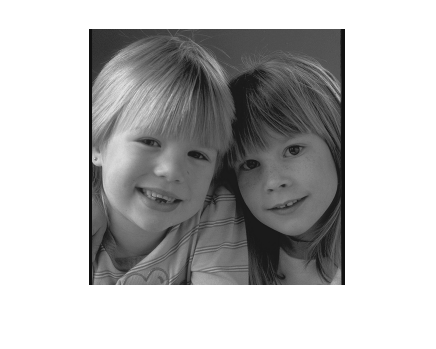

Gray = toGrayScale(X);
imshow(Gray);


toMark = readraw_color("..\srcImages\building_color.raw");

    "→Retrieving Image "    "..\srcImages\building_color.raw"    " ..."



mark = readraw_color("..\srcImages\cwru_logo_color.raw");

    "→Retrieving Image "    "..\srcImages\cwru_logo_color.raw"    " ..."



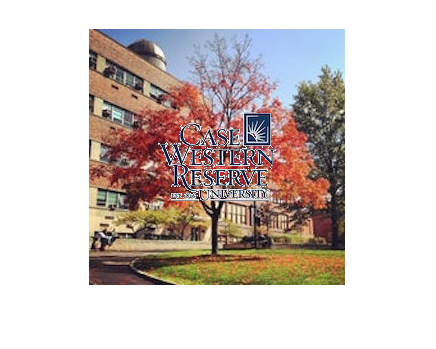


marked = waterMarkedCenterColor(toMark, mark);
imshow(marked);



mark = readraw("..\srcImages\cwru_logo_gray.raw");

    "→Retrieving Image "    "..\srcImages\cwru_logo_gray.raw"    " ..."



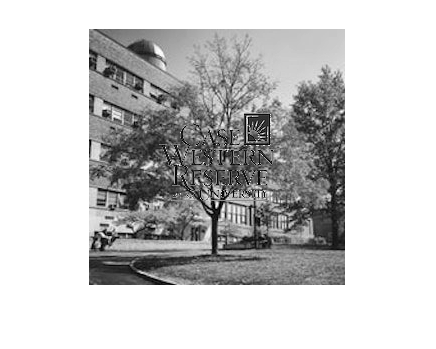

toMark = toGrayScale(toMark);

marked = waterMarkedCenterBW(toMark, mark);
imshow(marked);



jet = readraw_color("..\srcImages\F-16.raw");

    "→Retrieving Image "    "..\srcImages\F-16.raw"    " ..."



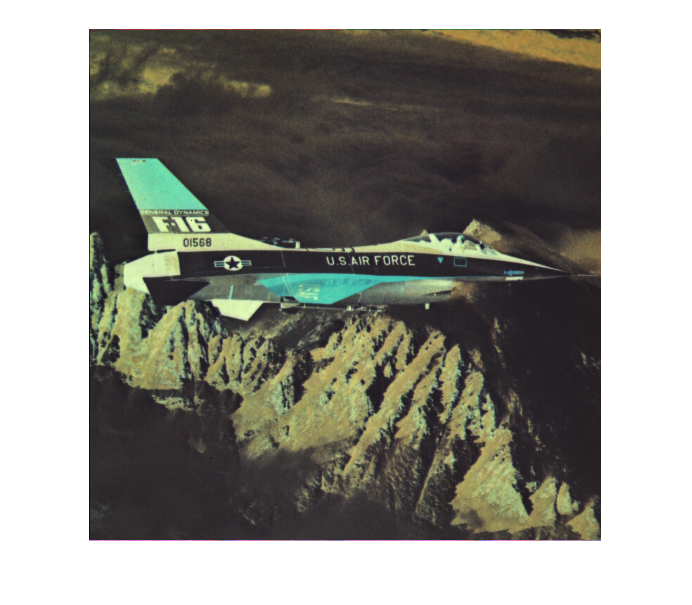

negJet = negativeImg(jet);
imshow(negJet);

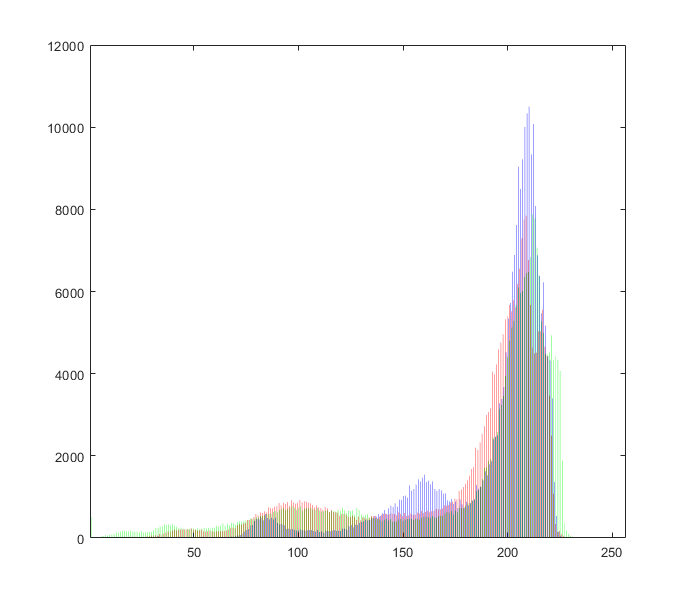


jetHist = histFor(jet, 3);
jetChart = bar(jetHist);
jetChart(1).FaceColor = 'r';
jetChart(2).FaceColor = 'g';
jetChart(3).FaceColor = 'b';

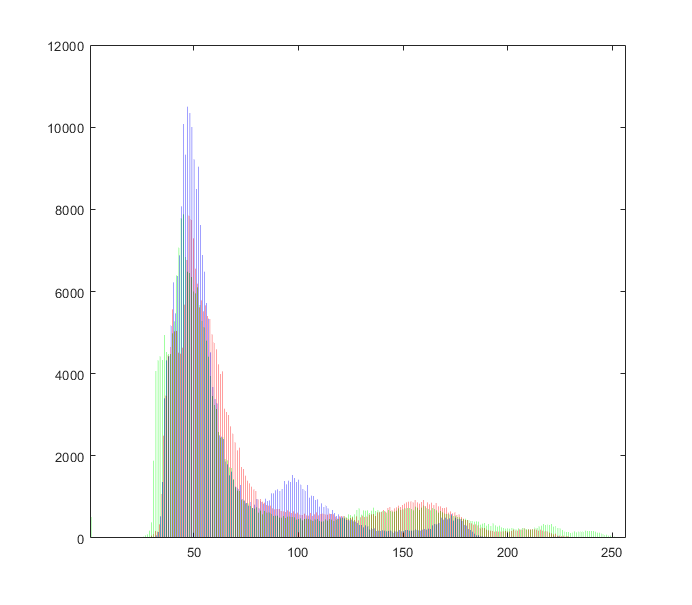


negHist = histFor(negJet, 3);
negChart = bar(negHist);
negChart(1).FaceColor = 'r';
negChart(2).FaceColor = 'g';
negChart(3).FaceColor = 'b';


%[w, h, ~] = size(mark);
%for x = 1:w
%    for y = 1:h
%        if ~isColorWhite(mark(x, y, :))
%            [r, g, b] = unpackColorPx(mark(x, y, :));
%            disp([r, g, b]);
%        end
%    end
%end